## Normalization

Consider an optimization problem of the form


$$\min f(\mathbf{x}) = (\mathbf{x}-\mathbf{c})^\top A (\mathbf{x}-\mathbf{c})\\
\; \:\mathrm{s.t.} \; \mathbf{x},\mathbf{c} \in \mathbb{R}^2 ,$$


with $A = \left[ \matrix{3\cdot 10^{-12} & 10^{-6} \cr 10^{-6} & 1} \right] $ and $\mathbf{c} = \left[\matrix{2\cdot 10^6 \cr 1} \right]$. Find the optimum analytically and then with the $\textit{grad\_descent}$ function below.

A = [3e-12,1e-6;1e-6,1];
c = [2e6;1];

% Solve with gradient descent algorithm
format long;
tic;
[x,nit,x_iter] = grad_descent(A,c,[0;0],1e4); % grad_descent(A,c,initial condition,max iterations)
toc

Elapsed time is 0.009876 seconds.



x

x =    0.079999998399840
   0.000000039998238


nit

nit =        10001


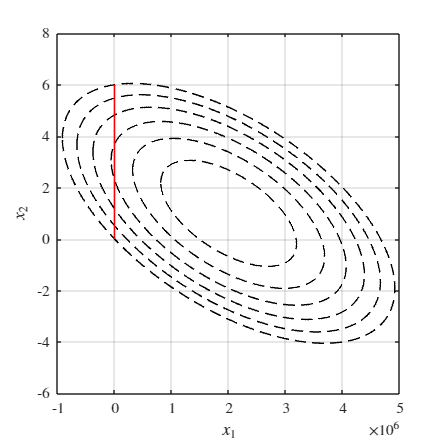

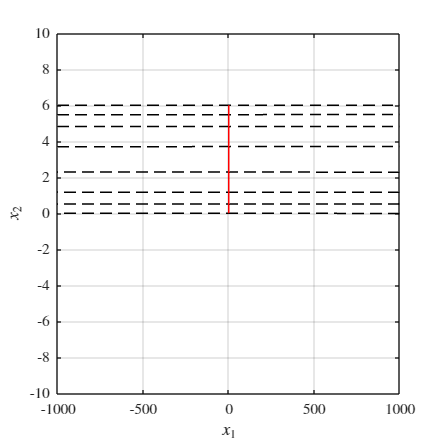


% Plot gradient descent iterations
grad_descent_plot(A,c,nit,x_iter,1);

- Is the problem convex? Why?

- Does the analytical result match the numerical results from the function? If not, why and can you improve the numerical results? (Hint: Play around with the initial conditions and the maximum number of iterations)

- Determine the number of iterations and the time required by the $\textit{grad\_descent}$ function to find the minimum (Hint: Stop if it is taking more than a minute).

Now see if you can find a faster solution (Hint: you do not need to change the algorithm).

% Normalize
A_n = diag([c(1) c(2)])*A*diag([c(1) c(2)]);
c_n = [1;1];

tic;
[z,nit,z_iter] = grad_descent(A_n,c_n,[0;0],1e4);
toc

Elapsed time is 0.005835 seconds.



z

z =    1.000000388465225
   0.999999818716228


nit

nit =    144



% Unnormalize
x = diag(c(1),c(2))*z;
fprintf("x_1 = %.0f, x_2 = %.0f",z(1)*c(1),z(2)*c(2))

x_1 = 2000001, x_2 = 1

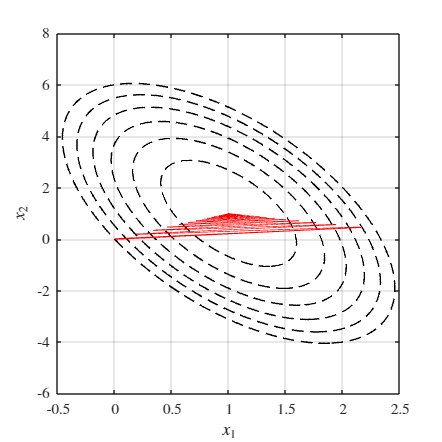


% Plot gradient descent iterations
grad_descent_plot(A_n,c_n,nit,z_iter,0);

How did you do it? How has the runtime improved compared to before?

function [x_out,niter,x] = grad_descent(A,c,x0,maxiter)
% Define functions
f1 = @(x1,x2) ([x1;x2]-c)'*A*([x1;x2]-c);
f2 = @(x) (x-c)'*A*(x-c);
grad = @(x) 2*A*(x-c);
% Optimal step size
step = 1/(max(eig(A))+min(eig(A)));
% Tolerance
tol = 1e-5;
% Initialize
x = zeros(2,maxiter);
gnorm = inf;
x(:,1) = x0;
niter = 1;
% Gradient descent algorithm
while gnorm >=tol && niter <= maxiter
    % calculate gradient:
    g = grad(x(:,niter));
    gnorm = norm(g);
    % take step:
    x(:,niter+1) = x(:,niter) - step*g;
    niter = niter+1;
end
x_out = x(:,niter);
end

function grad_descent_plot(A,c,nit,x_iter,flag)
    % Define functions
    f1 = @(x1,x2) ([x1;x2]-c)'*A*([x1;x2]-c);
    f2 = @(x) (x-c)'*A*(x-c);
    grad = @(x) 2*A*(x-c);
    % Level curves
    Ncurves = 7;
    Npoints = 1000;
    costs = 0:f1(0,0)/(Ncurves-1):f1(0,0);
    theta = 0:2*pi/(Npoints-1):2*pi;
    y = zeros(2,Npoints);
    x = zeros(2,Npoints);
    y(1,:) = cos(theta);
    y(2,:) = sin(theta);
    [S,D] = eig(A);
    T = inv(sqrtm(D)*inv(S));
    for i = 1:Npoints
        x(:,i) = T*y(:,i);
    end

    % Plot level curves and iterations
    figure('Position',4*[0 0 144 144]);
    hold on;
    grid on;
    box on;
    % set(gca,'FontSize',20);
    set(gca,'TickLabelInterpreter','latex');
    for i = 1:Ncurves
        plot(c(1)+sqrt(costs(i))*x(1,:),c(2)+sqrt(costs(i))*x(2,:),'--k','LineWidth',1);
    end
    plot(x_iter(1,1:nit),x_iter(2,1:nit),'-r','LineWidth',1);
    ylabel('$x_2$','Interpreter','latex');
    xlabel('$x_1$','Interpreter','latex');
    hold off;

    if flag 
    % Plot level curves and iterations
    figure('Position',4*[0 0 144 144]);
    hold on;
    grid on;
    box on;
    % set(gca,'FontSize',20);
    set(gca,'TickLabelInterpreter','latex');
    for i = 1:Ncurves
        plot(c(1)+sqrt(costs(i))*x(1,:),c(2)+sqrt(costs(i))*x(2,:),'--k','LineWidth',1);
    end
    plot(x_iter(1,1:nit),x_iter(2,1:nit),'-r','LineWidth',1);
    ylabel('$x_2$','Interpreter','latex');
    xlabel('$x_1$','Interpreter','latex');
    ylim([-1 1]*10);
    xlim([-1 1]*1e3);
    hold off;
    end

end